# Lab Session 3

**Multibody System Dynamics**

This lab session will focus on the equations of motion of a system using **dependent coordinates**. The central point of this approach are:

- **Lagrange multipliers**

## Equations of Motion

Let's consider a multibody system with a set of $n$ dependent coordinates ${\bf q}$ and a set of $r$ constraint equations


$${\bf \Phi} ({\bf q}) = {\bf 0}$$


Then, the lagrange equations can be written as:


$$\frac{d}{dt} \frac{\partial T}{\partial \dot{\bf q}} - \frac{\partial T}{\partial \bf q} = {\bf f} + {\bf A}^{\rm T} {\bf \lambda}$$


where ${\bf f}$ contains the $m$ generalized forces applied to the system (e.g., gravity, spring, friction, etc.), ${\bf f}_\text{con} = {\bf A}^{\rm T} {\bf \lambda}$ contains generalized constraint forces represented by the $r$ lagrange multipliers $\lambda_1 \ldots \lambda_r$, and ${\bf A}({\bf q}) = \frac{\partial \bf \Phi}{\partial \bf q}$ is the $(r \times n)$ constraint Jacobian matrix.

The kinetic energy can be written in terms of the generalized velocities $\dot{\bf q}$ using the $n\times n$ mass matrix ${\bf M(q)}$ as


$$T=\frac{1}{2} \dot{\bf q}^{\rm T} {\bf M} \dot{\bf q}$$


Then, the matrix form of the **equations of motion** can be written as:


$${\bf M} \ddot{\bf q} + {\bf c} = {\bf f} + {\bf A}^\text{T} {\bf \lambda}$$


where ${\bf c(q,\dot{q})} = \dot{\bf M} \dot{\bf q} - \frac{\partial T}{\partial {\bf q}} $ contains the velocity intependent terms of the inertial forces (Coriolis and centrifugal terms). In addition, the constraint equations can be written for the generalized acceleration as


$${\bf A} \ddot{\bf q} + {\bf w} = {\bf 0}$$


where ${\bf w} = \dot{\bf A}\dot{\bf q}$ are the constraint Coriolis terms.

Finally, the generalized acceleration $\ddot{\bf q}$ and the constraint forces ${\bf \lambda}$ can be obtained by solving the **dynamic equations**:


$$\left[ \matrix{ {\bf M} & -{\bf A}^\text{T} \cr {\bf A} & {\bf 0} } \right]
\left[ \matrix{ \ddot{\bf q} \cr {\bf \lambda} } \right] 
= \left[ \matrix{ {\bf f} - {\bf c} \cr -{\bf w} } \right]$$


# Assignment

## Double Pendulum

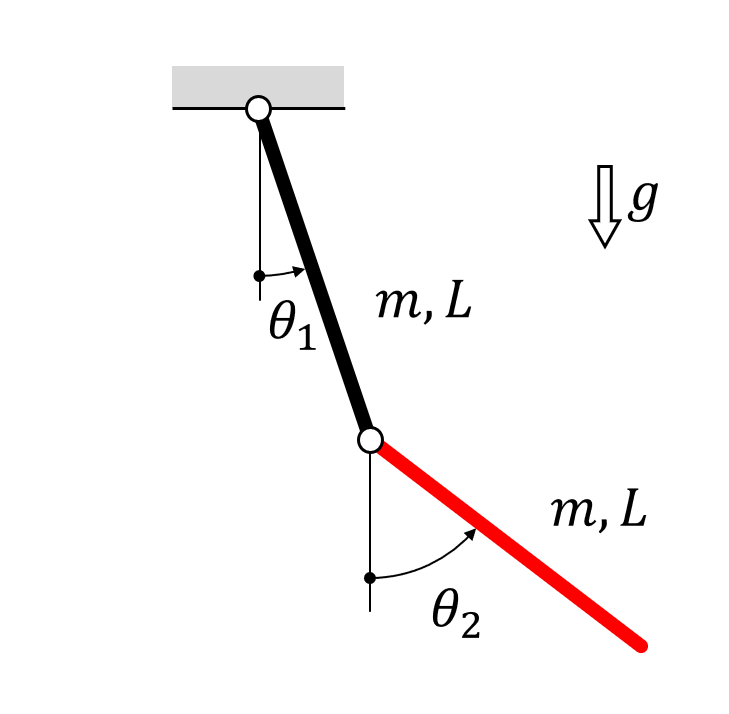

### 1. Simulation

Write a program to simulate the double pendulum starting from an initial orientation of the links. Use these lines as starting point:

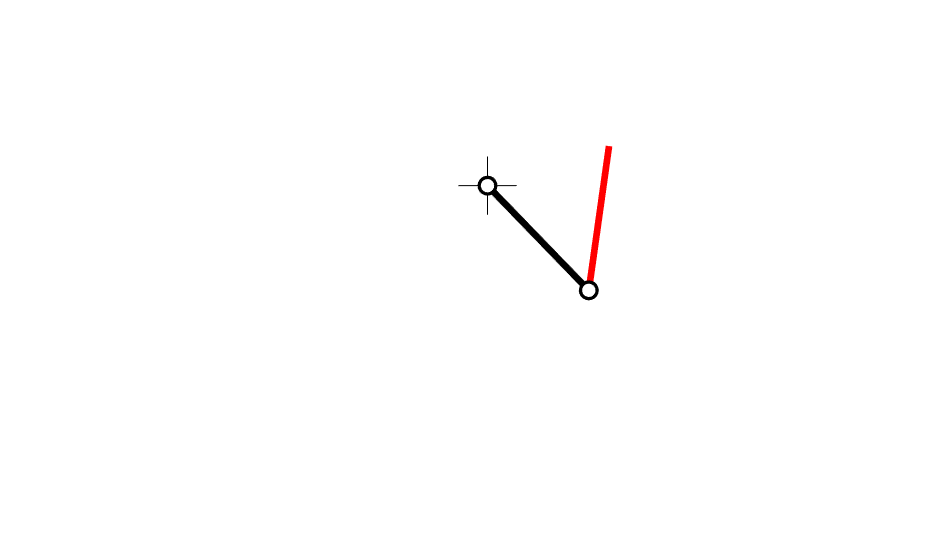

% Initialize Model and Viewer
model = DoublePendulum([m1, m2], [L1, L2]);
viewer = model.initViewer([-2, 2], [-2, 1]);

model.coordinateSet(1).initValue = pi/2;
model.coordinateSet(2).initValue = pi/2;

% Initialize variables
time = 5;
h = 0.01;
eulerImplicit = true;
solvePosition = true;
solveVelocity = false;

% Solve position problem
system = model.initSystem();
system.solvePositionProb();
model.update();
viewer.update();

% Simulation loop
steps = round(time / h);
for k = 1 : steps
    
    % Update System before calculations
    system.update();
    
    q = system.depenCoord;
    v = system.depenVeloc;
    
    % Solve dynamic equations
    M = system.mass;
    A = system.constJacob;
    c = system.coriolis;
    f = system.force;
    w = system.constCoriolis;

    lambda = (A * (M \ A')) \ (-A * (M \ (f - c)) - w);
    a = M \ (A' * lambda + f - c);
    
    if eulerImplicit
        % Euler Implicit
        v = v + a * h;
        q = q + v * h;
    else
        % Euler Explicit
        q = q + v * h;
        v = v + a * h;
    end
    
    system.depenCoord = q;
    system.depenVeloc = v;
    
    % Solve position problem
    if solvePosition
        system.model.update();
        system.updateIndependentCoordinates();
        system.solvePositionProb();
    end

    % Solve velocity
    if solveVelocity
        system.model.update();
        system.updateIndependentVelocity();
        system.solveVelocityProb();
    end
    
    % Update Model and Viewer after
    model.update();
    viewer.update();
    pause(h);
end

### 2. Constraint Error

Plot the **constraint coordinates** (`system.conPos)` for the first joints. What do you observe?

Try solving the **position problem** after updating the coordinates and velocities of the model by adding these lines at the end of the step:

% system.model.update();
% system.updateIndependentCoordinates();
% system.solvePositionProb();

Try solving the **velocity problem** as well.

% system.model.update();
% system.updateIndependentVelocity();
% system.solveVelocityProb();

### **Questions:**

- Run a 10 second simulation staring from $\theta_1 = \theta_2 = \frac{\pi}{2}$ and $\dot\theta_1 = \dot\theta_2 = 0$ using different time step sizes ($h = 0.1\,{\rm s}, 0.01\,{\rm s}, 0.001\,{\rm s} \dots $), and with and without solving **the position problem**. How does the model behaviour changes with these modifications?

- What does solving the position problem do? How does it improve the results?

- Plot and analyse the **constraint coordinates** (`conPos`) with and without solving the position problem for.